## MATLAB Code for Mapping-Environmental-Scenario-from-Sensor-Data 

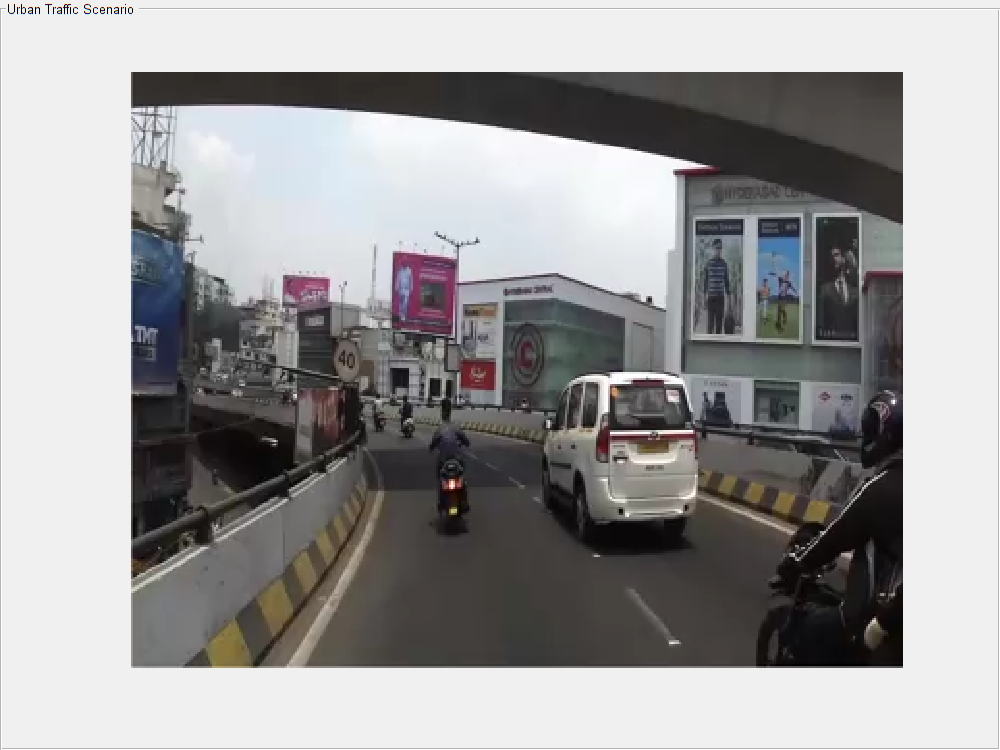

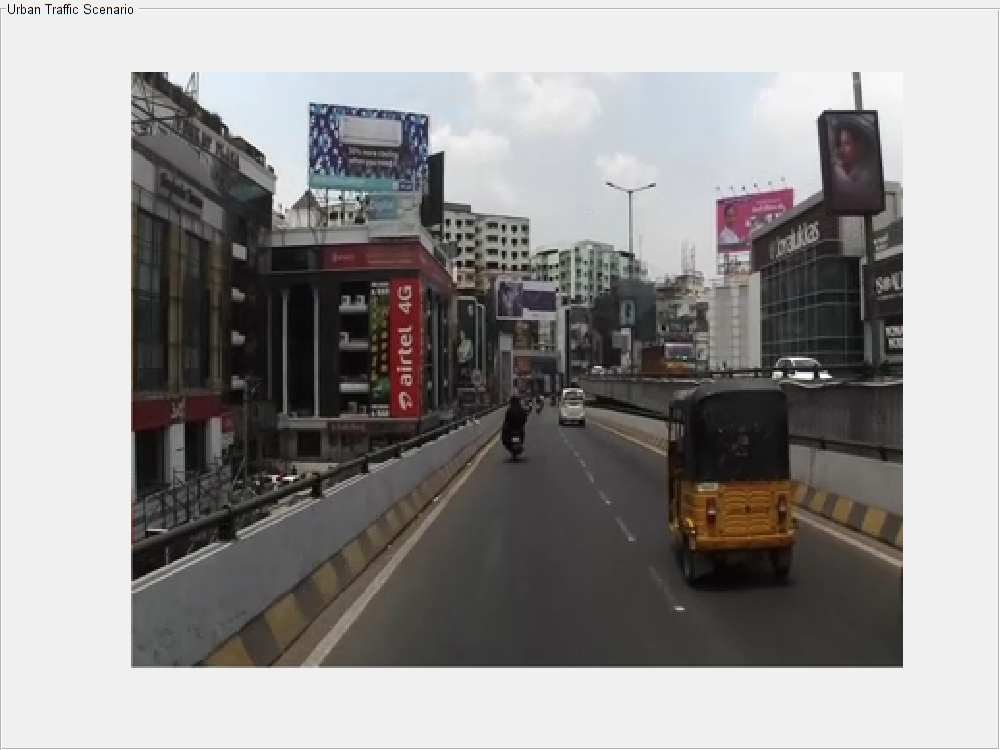

alt = 540

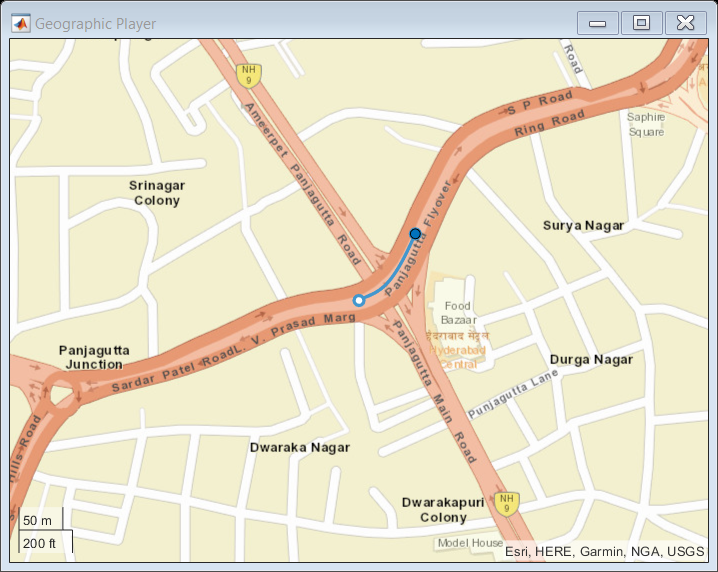

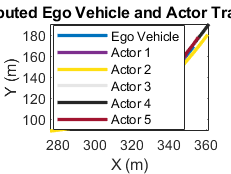

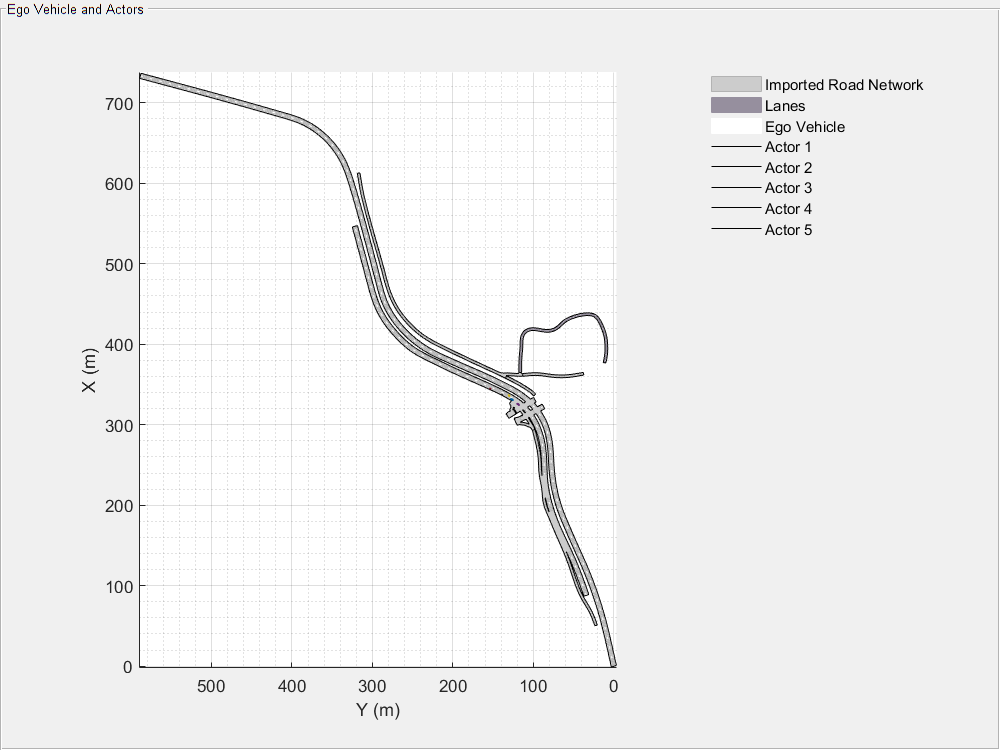

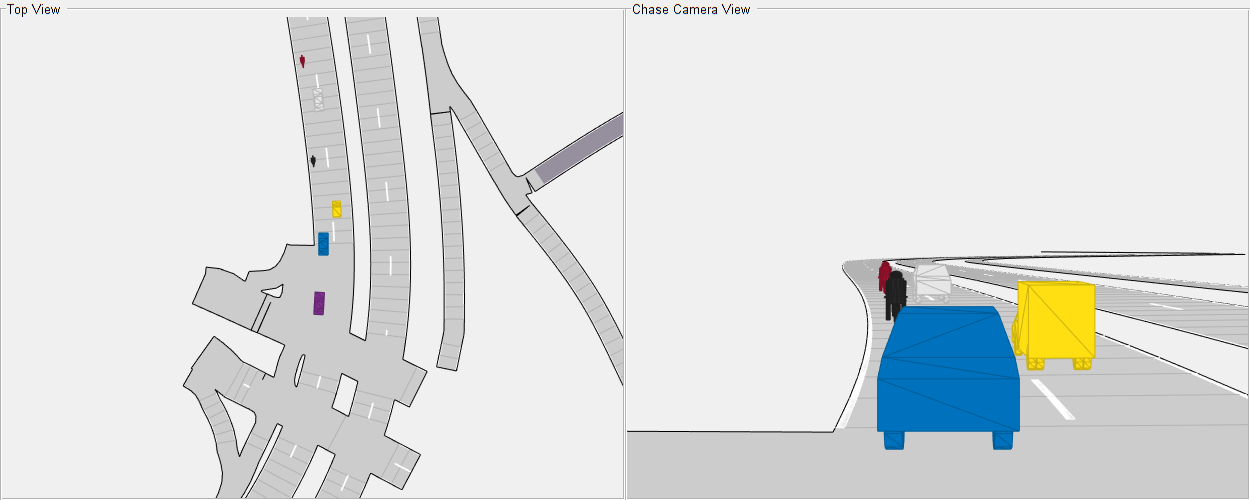

%Reference view from camera

vidObj = VideoReader("urbandrive.mp4");

fig = figure;
set(fig,Position=[0, 0, 800, 600]);
movegui(fig,"center");
pnl = uipanel(fig,Position=[0 0 1 1],...
    Title="Urban Traffic Scenario");
plt = axes(pnl);
while hasFrame(vidObj)
    vidFrame = readFrame(vidObj);
    image(vidFrame,Parent=plt);
    plt.Visible = "off";

    pause(1/vidObj.FrameRate);
end

%Import ASAM OpenDRIVE Road Network into Driving Scenario

scenario = drivingScenario;
openDRIVEFile = "OpenDRIVEUrban.xodr";
roadNetwork(scenario,"OpenDRIVE",openDRIVEFile);

#### Adding Ego Vehicle Data from GPS to Generated Scenario

%Adding Ego Vehicle Data from GPS to Generated Scenario
egoFile = "EgoUrban.txt";
egoData = helperGetEgoData(egoFile);

% To transform GPS coordinates to a XYZ cartesian coordinate frame. Latitude and longitude at origin of data from ASAM OpenDRIVE file are specified. 
% This point will also define the origin of the local coordinate system.
alt = 540.0 % Average altitude in Hyderabad, India

origin = [17.425853702697903, 78.44939480188313, alt]; % [lat, lon, altitude]

% Specified latitude and longitude of ego vehicle
lat = egoData.lat;
lon = egoData.lon;

% Computing waypoints of ego vehicle
[X,Y,~] = latlon2local(lat,lon,alt,origin);
egoWaypoints(:,1) =  X;
egoWaypoints(:,2) =  Y;


% Visualizing the GPS path of the ego vehicle using the geoplayer object.
zoomLevel = 17;
player = geoplayer(lat(1),lon(1),zoomLevel);
plotRoute(player,lat,lon);
for i = 1:size(lat,1)
    plotPosition(player,lat(i),lon(i));
end

%computing the speed and the heading angle values of the ego vehicle at each sensor data timestamp.
[egoSpeed,egoAngle] = helperComputeEgoData(egoData,X,Y);


%Adding the ego vehicle to the driving scenario.
ego = vehicle(scenario,ClassID=1,Name="Ego",...
    Length=3.6,Width=1.55,Height=1.6,...
    Mesh=driving.scenario.carMesh);

trajectory(ego,egoWaypoints,egoSpeed);

#### Adding Non-Ego Actors from Lidar Object Lists to Generated Scenario

nonEgoPosFile = "NonEgoUrban.txt";
nonEgoPropertiesFile = "NonEgoProperties.txt";
[nonEgoData, nonEgoProperties] = ...
    helperGetNonEgoData(nonEgoPosFile, nonEgoPropertiesFile);

actors = unique(nonEgoData(1).ActorID);
[nonEgoSpeed, nonEgoWaypoints] = ...
    helperComputeNonEgoData(egoData,...
    egoWaypoints,nonEgoData,egoAngle);

%Assigning meshes of vehicles according to classID
for i = 1:size(nonEgoProperties.ClassID,1)
    switch nonEgoProperties.ClassID(i)
        case 3
            nonEgoProperties.Mesh(i,1) = driving.scenario.bicycleMesh;
        case 2
            nonEgoProperties.Mesh(i,1) = driving.scenario.truckMesh;
        otherwise
            nonEgoProperties.Mesh(i,1) = driving.scenario.carMesh;
    end
end

for i = 1:size(actors,1)
        actor = vehicle(scenario,ClassID=1,...
            Length=nonEgoProperties.Length(i),...
            Width=nonEgoProperties.Width(i),...
            Height=nonEgoProperties.Height(i),...
            PlotColor=nonEgoProperties.Color(i,:),...
            Mesh=nonEgoProperties.Mesh(i));
        trajectory(actor,nonEgoWaypoints{i},nonEgoSpeed{i});
end


% Creating a custom figure window and define an axes object
fig = figure;
set(fig,Position=[0, 0, 800, 600]);
movegui(fig,"center");
hViewPnl = uipanel(fig,Position=[0 0 1 1],...
    Title="Ego Vehicle and Actors");
hCarPlt = axes(hViewPnl);

% Plotting the generated driving scenario.
plot(scenario,"Parent",hCarPlt);
axis([270 320 80 120]);
legend("Imported Road Network","Lanes","Ego Vehicle",...
    "Actor 1","Actor 2","Actor 3","Actor 4","Actor 5")
legend(hCarPlt,"boxoff");

figure,
plot(egoWaypoints(:,1),egoWaypoints(:,2),...
    Color=[0 0.447 0.741],LineWidth=2)
hold on
for i =1:size(actors,1)
    plot(nonEgoWaypoints{i}(:,1),...
        nonEgoWaypoints{i}(:,2),...
        Color=nonEgoProperties.Color(i,:),LineWidth=2)
end
axis("tight")
xlabel("X (m)")
ylabel("Y (m)")
title("Computed Ego Vehicle and Actor Trajectories")
legend("Ego Vehicle", "Actor 1", "Actor 2", "Actor 3",...
    "Actor 4","Actor 5","Location","Best")
hold off

#### Simulating and Visualizing virtually the Generated Scenario

% Creating a custom figure window to show the scenario and chase plot
figScene = figure(Name="Driving Scenario",...
    Tag="ScenarioGenerationDemoDisplay");
set(figScene,Position=[0, 0, 1000, 400]);
movegui(figScene,"center");

% Adding the chase plot
hCarViewPanel = uipanel(figScene,...
    Position=[0.5 0 0.5 1],Title="Chase Camera View");
hCarPlot = axes(hCarViewPanel);
chasePlot(ego,Parent=hCarPlot, Meshes="on");

% Adding the top view of the generated scenario
hViewPanel = uipanel(figScene,...
    Position=[0 0 0.5 1],Title="Top View");
hCarPlot = axes(hViewPanel);
chasePlot(ego,Parent=hCarPlot,Meshes="on",...
    ViewHeight=120, ViewPitch=90, ViewLocation=[0, 0]);

%Simulation run
while advance(scenario)
    pause(0.01)
end


warning("off","driving:scenario:ExportOpenScenarioODWarning");
export(scenario, "OpenSCENARIO", "PlaybackScenarioExample.xosc");
warning("on","driving:scenario:ExportOpenScenarioODWarning");

Below are all the helper functions which read as well as compute the speed / trajectories of both the ego and non-ego actors.

function [egoData] = helperGetEgoData(egoFile)

%Read the ego vehicle data from text file
fileID = fopen(egoFile);
content = textscan(fileID,'%f %f %f');
fields = {'lat','lon','Time'};
egoData = cell2struct(content,fields,2);
fclose(fileID);
end

function [egoSpeed, egoAngle] = ...
    helperComputeEgoData(egoData, X, Y)
egoTime = egoData.Time;
timeDiff = diff(egoTime);
points = [X Y];
difference  = diff(points, 1);
distance  = sqrt(sum(difference .* difference, 2));
egoSpeed = distance./timeDiff;
egoAngle = atan(diff(Y)./diff(X));
egoAngle(end+1) = egoAngle(end);
egoSpeed(end+1) = egoSpeed(end);
end

function [nonEgoPos, nonEgoProperties] = ...
    helperGetNonEgoData(nonEgoPosFile, nonEgoPropertiesFile)

% Reading the processed lidar data of non-ego actors from text file.
fileID1 = fopen(nonEgoPosFile);
content = textscan(fileID1,'%d %f %f %f %f');
newcontent{1} = content{1};
newcontent{2} = [content{2} content{3} content{4}];
newcontent{3} = content{5};
fields = {'ActorID','Position','Time'};
nonEgoPos = cell2struct(newcontent,fields,2);
fclose(fileID1);

fileID2 = fopen(nonEgoPropertiesFile);
content = textscan(fileID2,'%d %f %f %f %f %f %f');
newcontent{1} = content{1};
newcontent{2} = content{2};
newcontent{3} = content{3};
newcontent{4} = content{4};
newcontent{5} = [content{5} content{6} content{7}];
fields = {'ClassID','Length','Width','Height','Color'};
nonEgoProperties = cell2struct(newcontent,fields,2);
fclose(fileID2);
end


function [nonEgoSpeed, nonEgoWaypoints] = ...
    helperComputeNonEgoData(...
    egoData, egoWaypoints, nonEgoData, egoAngle)

actors = unique(nonEgoData.ActorID);
numActors = size(actors,1);

nonEgoWaypoints = cell(numActors, 1);
nonEgoSpeed     = cell(numActors, 1);

for i = 1:numActors
    id = actors(i);
    idx = find([nonEgoData.ActorID] == id);
    actorXData = nonEgoData.Position(idx,1);
    actorYData = nonEgoData.Position(idx,2);
    actorTime = nonEgoData.Time(idx);
    actorWaypoints = [0 0];
    
    %Computing the trajectory waypoints of non-ego actor
    [sharedTimeStamps,nonEgoIdx,egoIdx] = ...
        intersect(actorTime,egoData.Time,"stable");
    tempX = actorXData(nonEgoIdx);
    tempY = actorYData(nonEgoIdx);
    relativeX = -tempX .* cos(egoAngle(egoIdx)) + tempY .* sin(egoAngle(egoIdx));
    relativeY = -tempX .* sin(egoAngle(egoIdx)) - tempY .* cos(egoAngle(egoIdx));
    actorWaypoints(nonEgoIdx,1) = egoWaypoints(egoIdx,1) + relativeX;
    actorWaypoints(nonEgoIdx,2) = egoWaypoints(egoIdx,2) + relativeY;
    
    % Computing the speed values of non-ego actor
    timeDiff = diff(sharedTimeStamps);
    difference = diff(actorWaypoints, 1);
    distance   = sqrt(sum(difference .* difference, 2));
    actorSpeed = distance./timeDiff;
    actorSpeed(end+1) = actorSpeed(end);
    
    % Smoothing the trajectory waypoints of non-ego actor
    actorWaypoints = smoothdata(actorWaypoints,"sgolay");
    
    % Store the values of trajectory waypoints and speed computed of each non-ego actor
    nonEgoWaypoints(i) = {actorWaypoints};
    nonEgoSpeed(i) = {actorSpeed'};
end
end